## Primeira tentativa -- abordagem mais direta

Nessa situação abordada a gente em princípio assume que o coeficiente de arrasto ($\left.\beta \text{ }\right)$e a gravidade ($g$) são conhecidos e constantes. Nesse cenário, em cima da equação da dinâmica levantada, tem-se que:


$$\ddot{x}= \frac{0,0034ge^{-x/22000}\dot{x}^2}{2\beta} - g $$


Tomando essa equação por base, podemos tentar reescrever o sistema no espaço de estados (não-linear), em que serão considerados dois estados (a máxima ordem da minha equação diferencial é de 2º ordem) . Arbitrarei para este problema os estados:


$$\begin{array}{l}
x_1 =x\\
x_2 =\dot{x} 
\end{array}$$


Sendo assim, tentanto reespressar a equação de dinâmica não-linear, tem-se que:


$$\dot{\text{ }x_1 } =\dot{\text{ }x} =x_2$$



$$\dot{x_2} = \frac{0,0034ge^{-x/22000}\dot{x}^2}{2\beta} - g = \frac{0,0034ge^{-x_1/22000}x_2^2}{2\beta} - g $$


Isso obviamente depois de reescrever as equações e trocar os respectivos valores para os estados arbitrados (no caso $x_1$ e $x_2$).

Feito isso, no futuro teremos de encontrar as matrizes de estados linearizadas no entorno das melhores estimativas dos estados possíveis. A ideia então é proceder com a determinação da matriz $A$do sistema (aproximação de Taylor de 1º ordem).

Com a finalidade de simplificação, eu irei chamar as equações da forma:

 
$$\begin{array}{l}
f_1 =\dot{\text{ }x_1 } \\
f_2 =\dot{\text{ }x_2 } 
\end{array}$$


Com isso, a determinação da matriz $A$, tem-se que:


$$A = \left.\frac{\partial f(x)}{\partial x}\right|_{x = \hat{x}}
$$


Para para o caso de 2º ordem é dada por:


$$A={\left\lbrack \begin{array}{c}
\frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_1 }\text{ } & \frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_2 }\\
\frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_1 } & \frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_2 }
\end{array}\right\rbrack }_{x=\hat{\text{ }x} }$$


Sendo assim, teremos de determinar as derivadas acima:

- 
$$\frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_1 }=\frac{\text{ }\partial \text{ }\dot{\text{ }x_1 } }{\partial \text{ }x_1 }=\frac{\text{ }\partial \text{ }x_2 }{\partial \text{ }x_1 }=0$$


- 
$$\frac{\text{ }\partial \text{ }f_1 }{\partial \text{ }x_2 }=\frac{\text{ }\partial \text{ }\dot{x_1 \text{ }} }{\partial \text{ }x_2 }=\frac{\text{ }\partial \text{ }x_2 }{\partial \text{ }x_2 }=1$$


- $\frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_1 }=\frac{\text{ }\partial \text{ }\dot{\text{ }x_2 } }{\partial \text{ }x_1 }$=$\frac{\text{ }\partial \text{ }\left(\frac{\text{ }0,0034{\mathrm{ge}}^{\frac{-x_1 }{22000}} x_2^2 }{2\beta \text{ }}-g\right)}{\partial \text{ }x_1 }=$$-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }}$

- $\frac{\text{ }\partial \text{ }f_2 }{\partial \text{ }x_2 }=\frac{\text{ }\partial \text{ }\dot{\text{ }x_2 } }{\partial \text{ }x_2 }$=$\frac{\text{ }\partial \text{ }\left(\frac{\text{ }0,0034{\text{ge}}^{\frac{-x_1 }{22000}} x_2^2 }{2\beta \text{ }}-g\right)}{\partial \text{ }x_2 }=\frac{\text{ }0,0034{\mathrm{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}$

Em tese já temos a nossa matriz $A$não linear, que é dada por:


$$A\left(t\right)=\left\lbrack \begin{array}{c}
0 & 1\\
-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }} & \frac{\text{ }0,0034{\mathrm{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}
\end{array}\right\rbrack$$


Para esse caso, eu tentarei simplificar o problema reescrevendo essas equações dentro da matriz $A\left(t\right)$ por:


$$f_{21} =-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }}$$


e


$$f_{22} =\frac{\text{ }0,0034{\text{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}$$


que, ao final fica da forma:


$$A\left(t\right)=\left\lbrack \begin{array}{c}
0 & 1\\
f_{21}  & f_{22} 
\end{array}\right\rbrack$$


A nossa dinâmica final, linearizada (ponto a ponto) será algo da forma:


$$\left\lbrack \begin{array}{c}
\dot{\text{ }x_1 } \\
\dot{\text{ }x_2 } 
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{c}
0 & 1\\
f_{21}  & f_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
u_s 
\end{array}\right\rbrack$$


em que a gente supõe um erro na modelagem da dinâmica da aceleração (um ruído), pois o nosso modelo pode ter um erro na dinâmica da aceleração. Esse erro tem média zero (assumo isso).

Como dito logo acima, a gente considera a coeficiente de arrasto $\beta \text{ }$e aceleração da gravidade $g$ como sabidos e constantes. Dito isto, vamos agora determinar as equações do nosso sistema que serão utilizadas no filtro de Kalman.

A primeira coisa é determinar quem que é a matriz $\Phi \text{ }\left(t\right)$, que é dada por:


$$\Phi(t)=I+At+\frac{A^2t^2}{2!} +\frac{A^3t^3}{3!} + \dots$$


Na discretização, apenas a matriz $\Phi_k$entra nas equações de RIccati. E como visto ainda no capítulo 5, a gente não precisa determinar todos os termos dessa série. A ideia inicial é fazermos uma aproximação e pegaremos apenas os 2 primeiros termos. Assim, tem-se que:


$$\Phi \left(t\right)\approx I+\mathrm{At}=\left\lbrack \begin{array}{c}
1 & t\\
f_{21} t & \left(1+f_{22} t\right)
\end{array}\right\rbrack$$


e discretizando, tem-se que:


$$\Phi_k \approx I+{\mathrm{AT}}_s =\left\lbrack \begin{array}{c}
1 & T_s \\
f_{21} T_s  & \left(1+f_{22} T_s \right)
\end{array}\right\rbrack$$


em que $T_s$ é o tempo de amostragem. 

Ademais, importante lembrar que a nossa medida se dará apenas por meio de uma medida de distância (com ruído), de forma que:


$$x_k^∗ =\left\lbrack \begin{array}{c}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +v_k$$
 

Ou seja, a nossa matriz $C$do sistema já é linear (não precisa passar por linearização). De posse dessas informações iniciais, a gente consegue então determinar a matriz $R_k$, que é dada por:


$$R_k =E\left\lbrack v_k v_k^T \right\rbrack =\sigma_v^2$$


em que $\sigma_v$ é o desvio padrão da sistema de medida (radar). No nosso caso ele tem desvio padrão de 1000ft (a gente rodará outro exemplo lá na frente com um valor diferente para fins de exemplo).

Vamos agora tentar determinar quem que é a matriz $Q_k$, por meio de:


$$Q_k = \int_{0}^{T_s}\Phi(\tau)\textbf{Q}\Phi^{T}(\tau) d\tau$$


em que:


$$Q=E\left\lbrack w_k w_k^T \right\rbrack =E\left\lbrack \left\lbrack \begin{array}{c}
0\\
u_s 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & u_s 
\end{array}\right\rbrack \right\rbrack =E\left\lbrack \begin{array}{c}
0 & 0\\
0 & u_s^2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 0\\
0 & E\left\lbrack u_s^2 \right\rbrack 
\end{array}\right\rbrack$$


como o erro de modelagem é assumido gaussiano de média zero ($\eta =0$), tem-se que:


$$\sigma {\text{ }}^2 =E\left\lbrack {\left(\eta \text{ }-\overline{\eta \text{ }} \right)}^2 \right\rbrack =E\left\lbrack \eta {\text{ }}^2 \right\rbrack =\Psi \text{ }$$


Assim, a matriz $Q$ é dada por:


$$Q=\left\lbrack \begin{array}{c}
0 & 0\\
0 & \Psi {\text{ }}_s 
\end{array}\right\rbrack$$


Com isso, tem-se que:


$$Q_k =\int_0^{T_s } \left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & 0\\
0 & \Psi {\text{ }}_s 
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack }^T d\tau \text{ }$$


Separo o $\Psi_s \text{ }$para fora da integral.


$$Q_k =\Psi {\text{ }}_s \int_0^{T_s } \left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & 0\\
0 & 1
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
1 & 1\\
f_{21} \tau \text{ } & \left(1+f_{22} \tau \text{ }\right)
\end{array}\right\rbrack }^T d\tau$$


Que no final dá algo da forma:


$$Q_k =\Psi {\text{ }}_s \int_0^{T_s } \left\lbrack \begin{array}{c}
\tau {\text{ }}^2  & \left(\tau +f_{\mathrm{ss}} \tau {\text{ }}^2 \right)\\
\left(\tau +f_{\mathrm{ss}} \tau {\text{ }}^2 \right) & \left(1+2f_{22} \tau +f_{\mathrm{ss}}^2 \tau {\text{ }}^2 \right)
\end{array}\right\rbrack d\tau$$


Que resolvendo a integral:


$$Q_k =\Psi {\text{ }}_s \left\lbrack \begin{array}{c}
\frac{\text{ }T_s^3 }{3} & \left(\frac{\text{ }T_s^2 }{2}+f_{\text{ss}} \frac{\text{ }T_s^3 }{3}\right)\\
\left(\frac{\text{ }T_s^2 }{2}+f_{\text{ss}} \frac{\text{ }T_s^3 }{3}\right) & \left(T_s +f_{22} T_s^2 +f_{\text{ss}}^2 \frac{\text{ }T_s^3 }{3}\right)
\end{array}\right\rbrack$$


Sendo assim, a gente já conseguiu definir todas as matrizes para resolver as equações de Riccati. As únicas coisas que faltam apenas é determinar como que o nosso estado se propaga. Os próximos passos para resolvermos o problema é:

$\bullet$Propagar os estados da amostragem realizada no presente para o próximo instante de amostragem (diferentemente do que foi feito para o caso linear, a gente não consegue determinar isso de forma direta pois a nossa matriz $\Phi \text{ }\left(t\right)\text{ }$é apenas uma aproximação. Sendo assim a gente vai utilizar integração numérica).

Dessa forma, vamos pensar da seguinte em termos de boa estimativa (a que a gente pode tirar por meio da história) e melhor estimativa (a que a gente ajusta com base nos valores medidos por algum dispositivo).

- de maneira geral, dada a equação não-linear, uma boa estimativa que a gente tem para as derivadas estados do sistema no instante **k**, dado que a gente tem disponível até então as melhores estimativas do estado em **k-1:**


$$x\left\lbrack k\right\rbrack =x\left\lbrack k-1\right\rbrack +T_s ∗{\underbrace{f\left(x\left\lbrack k-1\right\rbrack \right)} }_{\left\lbrace \dot{x} \left\lbrack k-1\right\rbrack \right\rbrace }$$


Como a gente não mede todos os estados do vetor de estados de forma direta, a gente utiliza todos os dados disponíveis até o momento (ou seja até **k-1**) para ter uma boa estimativa de como que estará o vetor de estados no instante **k**.


$$\hat{x} \left\lbrack k\right\rbrack =\hat{x} \left\lbrack k-1\right\rbrack +T_s ∗{\underbrace{f\left(\hat{x} \left\lbrack k-1\right\rbrack \right)} }_{\left\lbrace \hat{\dot{x} } \left\lbrack k-1\right\rbrack \right\rbrace }$$


- A gente consegue ter uma melhor estimativa com base na boa estimativa que agente já tem e também com a medida utliizando o Filtro de Kalman Estendido.


$$\underbrace{x[k]}_\text{melhor estimativa} = \underbrace{x[k]}_\text{boa estimativa}  + K_{k}*(y(k) - C\underbrace{x[k]}_\text{boa estimativa})$$


Vamos, então, resolver o problema por meio das equações recém abordadas.

## Dinâmica do sistema e inserção do ruído

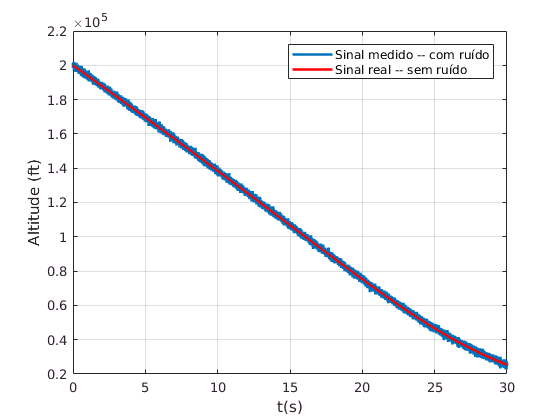

clear all; close all; clc;

% Tempo total de simulação e variáveis de passo de integração.
h      = 0.001;
Ttotal = 30;
Ts     = h;
t      = linspace(0, Ttotal, (Ttotal)/h + 1);  

% Parâmetros iniciais da nossa simulação (altitude e velocidade iniciais).
X{1} = [200000; -6000];

% Coeficiente de arrasto e constante gravitacional.
beta = 500;
g    = 32.2;

% Conforme descrito, para o referido exemplo o ruído de medida apresenta um
% desvio padrão de 1000 e média zero (variável de saída).
desvio_padrao = 1000;
ruido         = 0 + desvio_padrao*randn(1 + (Ttotal/h),1);

% Por meio da equação não-linear da queda de um corpo submetido à gravidade
% e um arrasto com coeficiente de arrasto constante, a gente integra a
% dinâmica e encontraremos a dinâmica da posição e velocidade.
for k = 1:max(size(t))
    % ==============================================================
    % As equações de Runge-Kuta de 2º ordem são simplificarmente, 
    % expressas por meio de:
    %
    %     c1 = f(x, t);
    %     c2 = f(x, t + h);
    %    
    %     x(k+1) = x(k) + (1/2)*(c1 + c2);
    % 
    % O que a gente tentará fazer aqui é reproduzir isso no inline.
    % ==============================================================
    
    % Pega os valores da estrutura 'x' (para condensar os resultados).
    x(1) = X{k}(1,1);
    x(2) = X{k}(2,1);
      
    % Cálculo de c1.
    x_d    = zeros(2,1);   
      
    x_d(1) = x(2);
    x_d(2) = 0.0034*g*exp(-x(1)/22000)*(x(2)^2)/(2*beta) - g;
    
    c1     = [x_d(1);
              x_d(2)];
        
    % Cálculo de c2 -- Nosso caso não depende do tempo.
    x_d = zeros(2,1);
      
    x_d(1) = x(2);
    x_d(2) = 0.0034*g*exp(-x(1)/22000)*(x(2)^2)/(2*beta) - g; 
    
    c2     = [x_d(1);
              x_d(2)];
    
    % Dinâmica 'final'.
    X{k+1} = X{k} + (1/2)*h*(c1 + c2);
end

% A medida 'real' do radar (ou seja, a realidade + ruído).
C = [1 0];
for k = 1:max(size(t))
   % Saída.
   y(k) = C*X{k} + ruido(k); 
   
   % Altitude.
   x(k) = X{k}(1,1);
end

% Plota o sinal real (em vermelho) e o sinal com ruído (azul).
plot(t, y, 'Linewidth', 2); hold on;
plot(t, x, 'r', 'Linewidth', 2); grid;
xlabel('t(s)');
ylabel('Altitude (ft)');
legend('Sinal medido -- com ruído', 'Sinal real -- sem ruído');

## Setagem inicial de preparação para o Filtro de Kalman Estendido

% Inicialmente, vamos falar que existe um 'match' perfeito entre a dinâmica
% real e o nosso modelo matemático. Para nosso primeiro exemplo, faremos:
u_s  = 0;

% Em consequência, tem-se que:
w     = [0; 
         u_s];
PSI_s = u_s^2;

% O ruído de medida é o do próprio radar. No instante inicia k = 1, tem-se:
R{1}  = desvio_padrao^2;

Matriz de Covariância no instante inicial.

% Inicializando a 'Matriz de Covariância' do nosso sistema.
P{1}(1,1) = desvio_padrao^2;
P{1}(2,2) = 20000;
P0        = P{1};

x1_hat(1)  = 200025;
x2_hat(1) = -6150;

Melhores estimativas iniciais para os estados.

x1_hat(1)  = 200025;
x2_hat(1) = -6150;

% Vetor de estados no instante inicial.
X_hat{1}  = [x1_hat(1);
             x2_hat(1)];

## Aplicação da Recursão

Em cima do equacionamento a partir da linearização dos sistema, em que:


$$\dot{\text{ }x_1 } =x_2$$



$$\dot{x_2} = \frac{0,0034ge^{-x_1/22000}x_2^2}{2\beta} - g $$


Como a gente não tem as variáveis $x_1$ e $x_2$ de maneira plena, a gente utiliza as melhores estimativas que temos a respeito, ou seja:


$$\hat{\dot{x}}_{1} = x_2$$



$$\hat{\dot{x}}_{2} = \frac{0,0034ge^{-\hat{x}_1/22000} \hat{x}_2^2}{2\beta} - g $$


Criando então o vetor de estados $\hat{x} ={\left\lbrack \begin{array}{c}
\hat{x_1 }  & \hat{\text{ }x_2 } 
\end{array}\right\rbrack }^T$. Sendo assim, a nossa boa estimativa para a derivada do vetor de estados se dá em cima da melhor estimativa que a gente tem até o momento:

for k = 1:max(size(t))
    
    % Estamos agora no instante 'k'. Sendo assim, a melhor estimativa 
    % que a gente tem da derivada do vetor de estados dizem respeito 
    % aos valores disponíveis até agora (que no caso são relativas ao
    % instante 'k-1').
    % ================================================================
    Xd_hat{k} = [ x2_hat(k);
                 (0.0034 * g * exp(-x1_hat(k)/22000) * x2_hat(k)^2)/ (2 * beta) - g];

Os parâmetros que serão utilizados de dinâmica do sistema linearizada, se realizará em cima, obviamente, da melhor estimativa que a gente tem dos estados (até o presente momento) e é dada na matriz $A\left(t\right)$. A gente utilizará apenas os termos não lineares da matriz $A\left(t\right)$, aqui denotados por $f_{21}$ e $f_{22}$.


$$A\left(t\right)=\left\lbrack \begin{array}{c}
0 & 1\\
-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }} & \frac{\text{ }0,0034{\text{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}
\end{array}\right\rbrack$$


em que:


$$f_{21} =-\frac{\text{ }0,0034{\text{ge}}^{\frac{{-x}_1 }{22000}} x_2^2 }{44000\beta \text{ }}$$


e


$$f_{22} =\frac{\text{ }0,0034{\text{ge}}^{\frac{-x_1 }{22000}} x_2 }{\beta \text{ }}$$


    % ---------------------------------------------------------------------
    % Até aqui nada demais, o que a gente tem é simplesmente aplicar as
    % regras de derivada e as equações do sistema, pois:
    %
    %
    % Fazendo uso das equações do Filtro de Kalman Estendido para esse
    % problema, tem-se que:
    % ---------------------------------------------------------------------
    
    % Determinação de f21 e f22.
    % ==========================
    f21 = -(0.0034 * exp(-x1_hat(k)/22000) * g * x2_hat(k)^2)/ (44000 * beta);
    f22 =  (0.0034 * exp(-x1_hat(k)/22000) * g * x2_hat(k)  )/ (beta);

De posse de $f_{21}$ e $f_{22}$, temos de determinar quem que é a matriz $Q_k$.


$$Q_k =\Psi {\text{ }}_s \left\lbrack \begin{array}{c}
\frac{\text{ }T_s^3 }{3} & \left(\frac{\text{ }T_s^2 }{2}+f_{22} \frac{\text{ }T_s^3 }{3}\right)\\
\left(\frac{\text{ }T_s^2 }{2}+f_{22} \frac{\text{ }T_s^3 }{3}\right) & \left(T_s +f_{22} T_s^2 +{f_{22} }^2 \frac{\text{ }T_s^3 }{3}\right)
\end{array}\right\rbrack$$


    % Matriz de erros de estado Q{k}.
    % ===============================
    % a) Primeira linha.
    q(1,1) = (Ts^3)/3;
    q(1,2) = (1/2)*(Ts^2) + (1/2) * f22 * (Ts^3);

    % b) Segunda linha.
    q(2,1) = (1/2)*(Ts^2) + (1/3) * f22 * (Ts^3);
    q(2,2) = Ts + f22*(Ts^2) + (1/3) * (f22^2) * (Ts^3);

    % Matriz 'Q{k}'.
    Q{k} = PSI_s*q;

A Matrix $R_k$ não muda, portanto:

    % Matriz 'R{k}'.
    % ==============
    R{k} = R{1};    

A outra matriz que precisa entrar nas equações de Riccati é a $\Phi_k$, que por meio da aproximação


$$\Phi_k \approx I+{\text{AT}}_s =\left\lbrack \begin{array}{c}
1 & T_s \\
f_{21} T_s  & \left(1+f_{22} T_s \right)
\end{array}\right\rbrack$$


é dada por:

    % Matriz de estados atualizada (para utilização nas eq. de Riccati).
    % ==================================================================
    % a_ Primeira linha.
    phi_k(1,1) = 1;
    phi_k(1,2) = Ts;

    % b) Segunda linha.
    phi_k(2,1) = f21 * Ts;
    phi_k(2,2) = (1 + f22 * Ts);
    
    % Aproximação de Taylor das equaçõs de estados.
    PHI{k} = phi_k;

Com isso, a gente faz todo o cálculo necessário das equações de Riccati, a saber:


$$M_k = \Phi_{k}P_{k-1}\Phi_{k}^T + Q_k
$$



$$K_k = M_{k}C^T(CM_kC^T+R_k)^{-1}$$



$$P_k = (I-K_kC)M_k$$


    % Determina-se a matriz de Kalman.
    % ================================
    if (k == 1)
        M{k} = PHI{k} * P0 * (PHI{k}') + Q{k}; 
        K{k} = M{k} * (C') * (C * M{k} * (C') + R{k})^(-1);
        P{k} = (eye(2) - K{k} * C) * M{k};
    else
        M{k} = PHI{k} * P{k-1} * (PHI{k}') + Q{k}; 
        K{k} = M{k} * (C') * (C * M{k} * (C') + R{k})^(-1);
        P{k} = (eye(2) - K{k} * C) * M{k};
    end

De posse de todas essas informações, precisamos obter as boas estimativas do sinal e, em seguida, melhora a estimativa (após aplicação do Filtro de Kalman).

Para determinação da boa estimativa do estado no instante **k** com base no passado **k-1** a gente simplesmente integra o sinal (Runge-Kutta, Euler etc). No caso a gente utilizará apenas a integração simples de Euler, em que:


$$\dot{\text{ }x} =f\left(x\right)$$


na discretização:


$$x\left\lbrack k\right\rbrack =x\left\lbrack k-1\right\rbrack +T_s ∗{\underbrace{f\left(x\left\lbrack k-1\right\rbrack \right)} }_{\left\lbrace \dot{x} \left\lbrack k-1\right\rbrack \right\rbrace }$$


Como a gente não tem os valores exatos, utilizaremos as estimativas do sinal:


$$\hat{x} \left\lbrack k\right\rbrack =\hat{x} \left\lbrack k-1\right\rbrack +T_s ∗{\underbrace{f\left(\hat{x} \left\lbrack k-1\right\rbrack \right)} }_{\left\lbrace \hat{\dot{x} } \left\lbrack k-1\right\rbrack \right\rbrace }$$


    % Boa estimativa para o sinal para o instante que a gente tem no
    % intante 'k' é simplesmente fazendo a integração de Euler. 
    % =====================================================================
    X_boa_estimativa{k}    = X_hat{k} + (Xd_hat{k} * Ts);

A gente pode melhorar essa estimativa por meio do Filtro de Kalman Estendido, em que a gente utiliza a melhor estimativa do sinal até o momento (chamado aqui de boa estimativa) e ajusta com base nos valores observados (no caso obtido via radar).


$$\underbrace{x[k]}_\text{melhor estimativa} = \underbrace{x[k]}_\text{boa estimativa}  + K_{k}*(y(k) - C\underbrace{x[k]}_\text{boa estimativa})$$


    % A gente pode melhorar essa estimativa, por meio do Filtro de Kalman
    % Estentido.
    X_melhor_estimativa{k+1} = X_boa_estimativa{k} + K{k}*(y(k) - C*X_boa_estimativa{k});

Essa melhor estimativa então deve ser propagada, ou seja:

    X_hat{k+1}  = X_melhor_estimativa{k+1};
    x1_hat(k+1) = X_hat{k+1}(1,1);
    x2_hat(k+1) = X_hat{k+1}(2,1);
end

Vamos plotar o resultado:

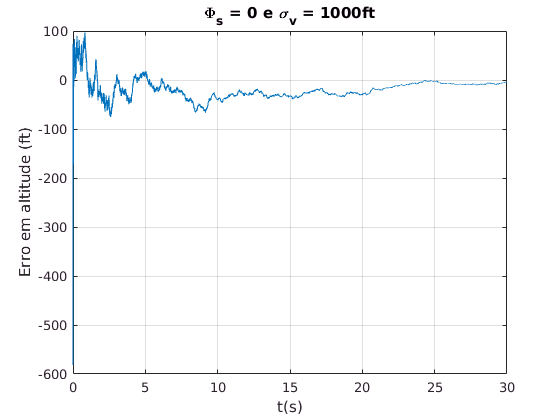

% Cálculo da medida de erro do sistema.
% =====================================
for k = 1:(max(size(X))-1)
    erro{k} = X{k} - X_hat{k};
    dist(k) = erro{k}(1,1);
    vel(k)  = erro{k}(2,1);
    
    % Resíduo.
    residuo(k) = y(k) - C*X_boa_estimativa{k};
    
    % Ganhos do filtro.
    k1(k) = K{k}(1,1);
    k2(k) = K{k}(2,1);
end

% Ajuste e plot do resultado.
% ===========================
figure;
plot(t, dist); grid;
xlabel('t(s)');
ylabel('Erro em altitude (ft)');
title('\Phi_s = 0 e \sigma_{v} = 1000ft');

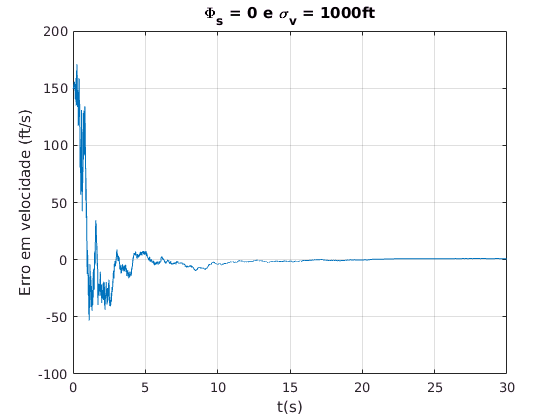

figure;
plot(t, vel); grid;
xlabel('t(s)');
ylabel('Erro em velocidade (ft/s)');
title('\Phi_s = 0 e \sigma_{v} = 1000ft');

Plota o resíduo do sistema.

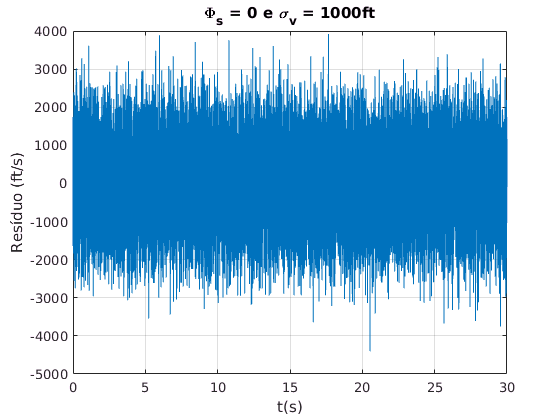

figure;
plot(t, residuo); grid;
xlabel('t(s)');
ylabel('Resíduo (ft/s)');
title('\Phi_s = 0 e \sigma_{v} = 1000ft');

Comportamento dos ganhos do Filtro de Kalman.

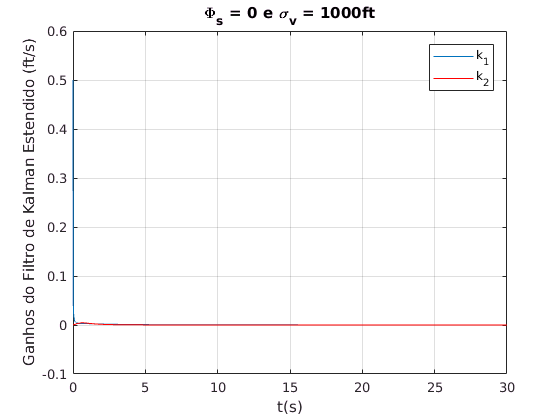

figure;
plot(t, k1); grid;
xlabel('t(s)');
ylabel('Ganho do Filtro de Kalman Estendido -- k_1');
title('\Phi_s = 0 e \sigma_{v} = 1000ft');

figure;
plot(t, k2); grid;
xlabel('t(s)');
ylabel('Ganho do Filtro de Kalman Estendido -- k_2');
title('\Phi_s = 0 e \sigma_{v} = 1000ft');